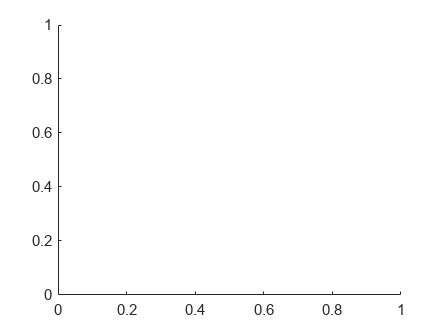

i = imread("ok.png");
text(size(i,2),size(i,1)+15, ...
    'Original Image 1','FontSize',7,'HorizontalAlignment','right');
unregistered = imread("cut.png");
text(size(unregistered,2),size(unregistered,1)+15,'Image 2','FontSize',7,'HorizontalAlignment','right');

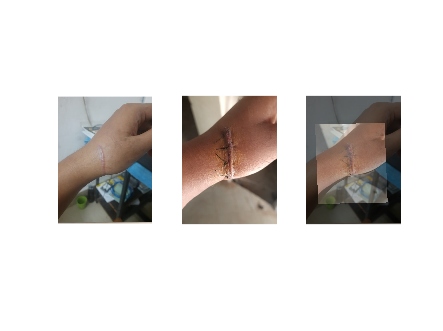

[movingPoints,fixedPoints] = cpselect(unregistered,i,'Wait',true);
t = fitgeotrans(movingPoints,fixedPoints,'affine');
Rfixed = imref2d(size(i));
registered = imwarp(unregistered,t,'OutputView',Rfixed);

subplot(1,3,1);imshow(i);
subplot(1,3,2);imshow(unregistered);
subplot(1,3,3);imshowpair(i,registered,'blend');